% This script creates a representative traces from Urovoid experiments. It
% supports one or two experimental recordings at this point.
% To use this script, push Run button in the Live Editor menu bar.  You
% will then get a dialog box to select one or two XLS files that were
% derived from UroVoid Analysis sessions.  After chosing the XLS file(s),
% you will then get a dialog box to select the folder containing the raw
% data Urovoid (*.txt) files corresponding to the XLS files.  If you are
% creating traces for two different XLS files, the *.txt files
% corresponding to those XLS files must be located in the same folder.
%
%   Date: February 2, 2026
%   Author: G. Herrera
%   email: gmherrer@uvm.edu
%   Version 1.1
%                    Version History:
%                     Jan 30, 2026   Version 1.0 - original release
%                     Feb 2, 2026    Version 1.1 - fixed bug where imported
%                                         XLS file contains numbers stored as
%                                         text caused cell2mat to fail.








clear

%% Select Excel summary files (1 or 2 experiments)

[xlsFiles, xlsPath] = uigetfile('*.xls', ...
    'Select Excel summary file(s)', ...
    'MultiSelect','on');

if isequal(xlsFiles,0)
    error('Excel file selection cancelled.');
end

if ischar(xlsFiles)
    xlsFiles = {xlsFiles};
end

nFiles = numel(xlsFiles);

if nFiles > 2
    error('Please select no more than two Excel files.');
end

Data = cell(1, nFiles);


%% Select directory containing TXT data files; we will search in this folder for txt files matching the xls files.

txtDir = uigetdir(pwd, 'Select the folder containing the TXT data files');
if isequal(txtDir,0)
    error('TXT folder selection cancelled.');
end

% Build a map of all TXT files in that folder (case-insensitive keys)
d = dir(fullfile(txtDir, '*.txt'));
txtMap = containers.Map;

for k = 1:numel(d)
    txtMap(lower(d(k).name)) = fullfile(txtDir, d(k).name);
end



%% Loop through experiments

for i = 1:nFiles

    xlsFullPath = fullfile(xlsPath, xlsFiles{i});

    %% ===== Read "Total Voids – Details" sheet =====

    sheets = sheetnames(xlsFullPath);

    idx = contains(lower(sheets), 'total voids') & ...
        contains(lower(sheets), 'details');

    assert(any(idx), ...
        'Could not find worksheet containing "Total Voids" and "Details".');

    voidDetails = readcell(xlsFullPath, ...
        'Sheet', sheets{find(idx,1)});


    % Row 1: filename
    assert(strcmpi(voidDetails{1,1},'filename:'), ...
        'Expected "filename:" in row 1 column 1 (%s).', xlsFiles{i});

    txtNameFromXls = voidDetails{1,2};

    if ~endsWith(txtNameFromXls,'.txt','IgnoreCase',true)
        txtNameFromXls = [txtNameFromXls '.txt'];
    end

    txtKey = lower(txtNameFromXls);

    if ~isKey(txtMap, txtKey)
        error(['No *.txt file with the name "%s" could be located to match ' ...
            'the excel file.\nPlease reload files and make sure xls and txt files match.'], ...
            txtNameFromXls);
    end

    txtFullPath = txtMap(txtKey);

    % Row 2: scale name
    assert(strcmpi(voidDetails{2,1},'scale:'), ...
        'Expected "scale:" in row 2 column 1 (%s).', xlsFiles{i});

    scaleName = string(voidDetails{2,2});

    
    %% ===== Load TXT file =====

    txtRaw = readcell(txtFullPath, ...
        'FileType','text', ...
        'Delimiter','\t');

    headerRow    = 11;   % row containing scale names
    dataStartRow = 12;   % numeric data starts here

    % Time is always column 1. Time column is in SECONDS → convert to HOURS
    Data{i}.timeHrs = colToNumeric(txtRaw(dataStartRow:end, 1)) / 3600;


    % Find scale column by matching header row text
    scaleHeaders = string(txtRaw(headerRow, :));
    scaleColIdx  = find(strcmpi(scaleHeaders, scaleName), 1);

    assert(~isempty(scaleColIdx), ...
        'Scale "%s" not found in TXT file (%s).', ...
        scaleName, txtNameFromXls);

    % Extract scale signal
    Data{i}.scaleSignal = colToNumeric(txtRaw(dataStartRow:end, scaleColIdx));

   

    %% ===== Extract Void Start Times and Void Volumes =====

    headerRow = 9;
    colNames  = string(voidDetails(headerRow,:));

    startColIdx = find(strcmpi(colNames, 'Void Start Time (HRS)'), 1);
    volColIdx   = find(strcmpi(colNames, 'Void Vol (ml)'), 1);

    assert(~isempty(startColIdx), ...
        '"Void Start Time (HRS)" column not found (%s).', xlsFiles{i});
    assert(~isempty(volColIdx), ...
        '"Void Vol (ml)" column not found (%s).', xlsFiles{i});

    startCol = voidDetails(headerRow+1:end, startColIdx);
    volCol   = voidDetails(headerRow+1:end, volColIdx);

    startNum = colToNumeric(startCol);
    volNum   = colToNumeric(volCol);

    keep = ~isnan(startNum) & ~isnan(volNum);

    Data{i}.startTimes = startNum(keep);
    voidVols           = volNum(keep);


    %% ===== Find peak values corresponding to each  void using scale signal at baseline and adding void volumes =====

    timeVec  = Data{i}.timeHrs;
    startVec = Data{i}.startTimes;

    idx = zeros(size(startVec));
    tol = 1e-6;   % hours (~3.6 ms)

    for k = 1:numel(startVec)
        [dt, ii] = min(abs(timeVec - startVec(k)));

        assert(dt < tol, ...
            'Void start time %.6f hrs not found in timeHrs within tolerance (%s).', ...
            startVec(k), xlsFiles{i});

        idx(k) = ii;
    end

    voidBaselines = Data{i}.scaleSignal(idx);

    Data{i}.peakValues = voidBaselines + voidVols; %find the scale value for each void by adding the void volume to the scale signal at the start of each void


    %% ===== Load remaining Excel sheets =====

    Data{i}.binInfoTable   = readcell(xlsFullPath, 'Sheet','Binning Parameters');
    Data{i}.cycleTimeTable = readcell(xlsFullPath, 'Sheet','Light-Dark Cycle Times');

    fprintf('Loaded experiment %d: %s\n', i, txtNameFromXls);

end

Loaded experiment 1: 20250929_42,55,56,67_females.txt


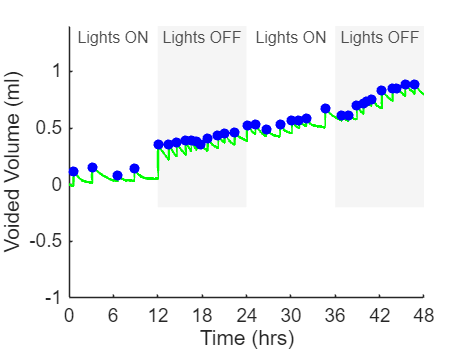




%% Setup time, scale, and data offsets for each file

for i = 1:nFiles
    Data{i}.startDataTime = Data{i}.binInfoTable{1,2}; %starting Bin Time, defines start of period used in analysis
    Data{i}.startDataTimeIdx = find(Data{i}.timeHrs == Data{i}.startDataTime);
    Data{i}.endDataTime = Data{i}.binInfoTable{3,2}; %ending Bin Time, defines end of period used in analysis
    Data{i}.timeOffset = Data{i}.timeHrs - Data{i}.startDataTime; %convert times relative to start of data analysis
    Data{i}.startTimesOffset = Data{i}.startTimes - Data{i}.startDataTime;  %convert void start times relative to start of data analysis
    Data{i}.scaleOffset = Data{i}.scaleSignal - Data{i}.scaleSignal(Data{i}.startDataTimeIdx); %reference scale signal to start of recording
    Data{i}.peakValuesOffset = Data{i}.peakValues - Data{i}.scaleSignal(Data{i}.startDataTimeIdx); %referece peak values to the start of recording
    
    %%%% Nearest-neighbor index lookup to assing indicies for void start times
    timeVecAbs = Data{i}.timeHrs;
    timeVecOff = Data{i}.timeOffset;

    startAbs = Data{i}.startTimes;
    startOff = Data{i}.startTimesOffset;

    Data{i}.startTimesIdx = nearestTimeIndex(timeVecAbs, startAbs);
    Data{i}.startTimesIdxOffset = nearestTimeIndex(timeVecOff, startOff);

    %%%%
end


% Setup cycle times for each file with time offset relative to the starting
% analysis cycle

for i = 1:nFiles

    CTT = Data{i}.cycleTimeTable;

    % Table definitions based on "Light-Dark Cycle Times" Sheet in excel
    % file
    hdrRow   = 1; %row 1 contains header; column labels
    nameCol  = 1; %column 1 is the Cycle Name
    startCol = 2; %column 2 is the cycle start time in hours
    endCol   = 3; %column 3 is the cycle end time in hours

    % Data rows are everything below header row
    dataRows = (hdrRow+1):size(CTT,1);

    % Start with a copy
    CTT_off = CTT;

    % Convert start/end columns to numeric for data rows
    startAbs = colToNumeric(CTT(dataRows, startCol));
    endAbs   = colToNumeric(CTT(dataRows, endCol));

    % Keep only valid numeric rows (skip blanks)
    valid = ~isnan(startAbs) & ~isnan(endAbs);

    % Apply offset relative to start of analysis
    startOff = startAbs(valid) - Data{i}.startDataTime;
    endOff   = endAbs(valid)   - Data{i}.startDataTime;

    % Write back into the offset table (preserve header row)
    tmpStart = CTT_off(dataRows, startCol);
    tmpEnd   = CTT_off(dataRows, endCol);

    % Only overwrite valid numeric rows
    tmpStart(valid) = num2cell(startOff);
    tmpEnd(valid)   = num2cell(endOff);

    CTT_off(dataRows, startCol) = tmpStart;
    CTT_off(dataRows, endCol)   = tmpEnd;

    Data{i}.cycleTimeTableOffset = CTT_off;

    % Store clean vectors for downstream use (no cell2mat anywhere)
    Data{i}.cycleNames       = string(CTT(dataRows(valid), nameCol));
    Data{i}.cycleStartOffset = startOff;
    Data{i}.cycleEndOffset   = endOff;

    % Store absolute cycle start and end times too
    Data{i}.cycleStartAbsHrs = startAbs(valid);
    Data{i}.cycleEndAbsHrs   = endAbs(valid);

end





% find the cycle duration for each recording.
for i = 1:nFiles

    binInfo = Data{i}.binInfoTable;

    %% --- Extract Bin Start Time (Hrs) ---

    if istable(binInfo)
        % Label may be row name or first column
        if ~isempty(binInfo.Properties.RowNames) && ...
           any(strcmp(binInfo.Properties.RowNames, 'Bin Start Time (Hrs)'))

            binStartTime = binInfo{'Bin Start Time (Hrs)', :};

        else
            rowIdx = strcmp(binInfo{:,1}, 'Bin Start Time (Hrs)');
            assert(any(rowIdx), ...
                'Bin Start Time (Hrs) not found in binInfoTable (File %d).', i);

            binStartTime = binInfo{rowIdx, 2};
        end

    elseif iscell(binInfo)
        % Assume label in column 1, value in column 2
        rowIdx = strcmp(binInfo(:,1), 'Bin Start Time (Hrs)');
        assert(any(rowIdx), ...
            'Bin Start Time (Hrs) not found in binInfoTable (File %d).', i);

        binStartTime = binInfo{rowIdx, 2};

    elseif isstruct(binInfo)
        % Rare but handle it
        assert(isfield(binInfo, 'BinStartTimeHrs'), ...
            'binInfoTable struct missing BinStartTimeHrs field (File %d).', i);

        binStartTime = binInfo.BinStartTimeHrs;

    else
        error('Unsupported binInfoTable type for File %d.', i);
    end

    binStartTime = binStartTime(1);  % enforce scalar

    %% --- Find matching cycle and compute duration ---

    CTT = Data{i}.cycleTimeTable;

    % 1) Get headers from the first row
    headers = lower(strtrim(string(CTT(1,:))));

    % 2) Identify the Start/End time columns by header text
    startCol = find(contains(headers, "start") & contains(headers, "time"), 1);
    endCol   = find(contains(headers, "end")   & contains(headers, "time"), 1);

    assert(~isempty(startCol) && ~isempty(endCol), ...
        'Could not locate Start/End time columns in cycleTimeTable (File %d).', i);

    % 3) Extract data rows (skip header row)
    dataRows = 2:size(CTT,1);

    % 4) Convert columns to numeric (handles numeric + text)
    cycleStartTimes = colToNumeric(CTT(dataRows, startCol));
    cycleEndTimes   = colToNumeric(CTT(dataRows, endCol));

    % Optional: ignore completely empty rows
    valid = ~isnan(cycleStartTimes) & ~isnan(cycleEndTimes);
    cycleStartTimes = cycleStartTimes(valid);
    cycleEndTimes   = cycleEndTimes(valid);

    % ---- Now your existing matching logic works ----
    tol = 1e-6;
    matchIdx = find(abs(cycleStartTimes - binStartTime) < tol, 1);

    assert(~isempty(matchIdx), ...
        'No cycle start time matching Bin Start Time (Hrs) (File %d).', i);

    Data{i}.cycleDuration = cycleEndTimes(matchIdx) - cycleStartTimes(matchIdx);


end


%Find the cycle start times for the analyzed cycles (relative to time 0
%being start of analysis). These are used for generating light/dark cycle
%bars in the traces.
for i = 1:nFiles

    %% --- Extract Bin Start / End Cycle names ---
    binInfo = Data{i}.binInfoTable;

    if istable(binInfo)
        % Label in first column
        startIdx = strcmp(binInfo{:,1}, 'Bin Start Cycle');
        endIdx   = strcmp(binInfo{:,1}, 'Bin End Cycle');

        assert(any(startIdx) && any(endIdx), ...
            'Bin Start/End Cycle not found in binInfoTable (File %d).', i);

        startCycleName = string(binInfo{startIdx, 2});
        endCycleName   = string(binInfo{endIdx, 2});

    elseif iscell(binInfo)
        startIdx = strcmp(binInfo(:,1), 'Bin Start Cycle');
        endIdx   = strcmp(binInfo(:,1), 'Bin End Cycle');

        assert(any(startIdx) && any(endIdx), ...
            'Bin Start/End Cycle not found in binInfoTable (File %d).', i);

        startCycleName = string(binInfo{startIdx, 2});
        endCycleName   = string(binInfo{endIdx, 2});

    else
        error('Unsupported binInfoTable type (File %d).', i);
    end

    %% --- Locate cycles in cycleTimeTableOffset ---
    cycleNames      = Data{i}.cycleNames;
    cycleStartTimes = Data{i}.cycleStartOffset;

    startCycleIdx = find(cycleNames == startCycleName, 1);
    endCycleIdx   = find(cycleNames == endCycleName,   1);

    assert(~isempty(startCycleIdx) && ~isempty(endCycleIdx), ...
        'Start or end cycle not found in cycleTimeTableOffset (File %d).', i);

    %% --- Ensure proper ordering ---
    if startCycleIdx > endCycleIdx
        warning('Start cycle occurs after end cycle (File %d). Reversing.', i);
        idxRange = endCycleIdx:startCycleIdx;
    else
        idxRange = startCycleIdx:endCycleIdx;
    end

    %% --- Store analyzed cycle start times ---
    Data{i}.analyzedCycleStartTimes = cycleStartTimes(idxRange);
    Data{i}.analyzedCycleNames = cycleNames(idxRange);

end

%%% Generate Plots


recColor = [0.9 0.9 0.9]; %Color of the dark bar
onTxt = 'Lights ON';
offTxt = 'Lights OFF';
lColor = {'green', 'red'}; %colors for lines
lWidth = 1.2; %line width for scale traces
sColor = {'blue', 'cyan'}; %colors for void markers
sSize  = 25; %size for void marker scatter plot symbol

figure; hold on

for i = 1:nFiles
    plot(Data{i}.timeOffset, Data{i}.scaleOffset, ...
        lColor{i}, 'LineWidth', lWidth);

    scatter(Data{i}.timeOffset(Data{i}.startTimesIdxOffset), ...
        Data{i}.peakValuesOffset, sSize, ...
        'MarkerFaceColor', sColor{i}, ...
        'MarkerEdgeColor','none');
end

yl = ylim;              % global Y range after all traces are generated
yText = yl(2) - 0.02*range(yl);

%%%Generate Light/Dark Cycle patches and labels

cycleNames = Data{1}.cycleNames;
cycleStart = Data{1}.cycleStartOffset;
cycleEnd   = Data{1}.cycleEndOffset;


darkIdx = contains(lower(cycleNames), 'dark');

% ---- Draw OFF patches ----
for k = find(darkIdx)'
    patch([cycleStart(k) cycleEnd(k) cycleEnd(k) cycleStart(k)], ...
          [yl(1) yl(1) yl(2) yl(2)], ...
          recColor, ...
          'EdgeColor','none', ...
          'FaceAlpha',0.4);
end

%%%%% Place cycle labels
for k = 1:numel(cycleNames)

    if darkIdx(k)
        labelTxt = offTxt;
    else
        labelTxt = onTxt;
    end

    xText = mean([cycleStart(k), cycleEnd(k)]);

    text(xText, yText, labelTxt, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','top', ...
        'FontSize',8, ...
        'Color',[0.3 0.3 0.3], ...
        'Clipping','on');
end

%%% Fix stacking order of plot elements
uistack(findobj(gca,'Type','patch'),'bottom');
uistack(findobj(gca,'Type','line'),'top');
uistack(findobj(gca,'Type','scatter'),'top');

%%% Format axes
xlabel('Time (hrs)')
ylabel('Voided Volume (ml)')

minX = Data{1}.analyzedCycleStartTimes(1);
maxX = Data{1}.analyzedCycleStartTimes(end) + Data{1}.cycleDuration;

xlim([minX maxX])
xticks(minX:Data{1}.cycleDuration/2:maxX)
ylim([-1 yl(2)])


set(gca,'Box','off');





%%%%%%%%% Helper functions

function v = colToNumeric(c)
% Convert a cell column (numeric, char, string, empty) to numeric vector.
% Non-convertible entries become NaN.

c = c(:);
v = nan(size(c));

for k = 1:numel(c)
    x = c{k};

    if isempty(x)
        v(k) = NaN;

    elseif isnumeric(x)
        % accept scalar or take first element
        if isscalar(x)
            v(k) = x;
        else
            v(k) = x(1);
        end

    else
        s = strtrim(string(x));
        % If your locale ever uses comma decimals, uncomment next line:
        % s = replace(s, ",", ".");
        v(k) = str2double(s);
    end
end
end



function idx = nearestTimeIndex(timeVec, queryTimes)
% Return indices in timeVec closest to each query time.
% timeVec: Nx1 numeric, queryTimes: Mx1 numeric
% idx: Mx1 integer indices (always >= 1)

timeVec = timeVec(:);
queryTimes = queryTimes(:);

idx = zeros(size(queryTimes));

for k = 1:numel(queryTimes)
    [~, ii] = min(abs(timeVec - queryTimes(k)));
    idx(k) = ii;
end
end



